This system is used to model the evolution of concentrations of glucose $G$, maltose $M$, maltotriose $N$, yeast $X$, and ethanol $E$ during the fermentation of beer (Gee and Ramirez, 1998). 


$$ \frac{dG}{dt} = -\mu_1 X,  \qquad \mu_1(G) = \frac{V_G G}{K_G+G}\\
 \frac{dM}{dt} = -\mu_2 X,  \qquad \mu_2(G,M) = \frac{V_M M}{K_M+M} \frac{K_{iG}}{K_{iG}+G} \\
\frac{dN}{dt} = -\mu_3 X,  \qquad \mu_3(G,M,N) = \frac{V_N N}{K_N+N} \frac{K_{iG}}{K_{iG}+G} \frac{K_{iM}}{K_{iM}+M} \\
 \frac{dX}{dt} = (0.134\mu_1 + 0.268\mu_2 + 0.402\mu_3 )X \\
    \frac{dE}{dt} = (1.92\mu_1+3.84\mu_2+5.76\mu_3)X
$$



$$E(0)=0,\quad G(0), M(0), N(0), X(0) \;\text{given}$$


The function `beer_op` is defined at the end of this file. 

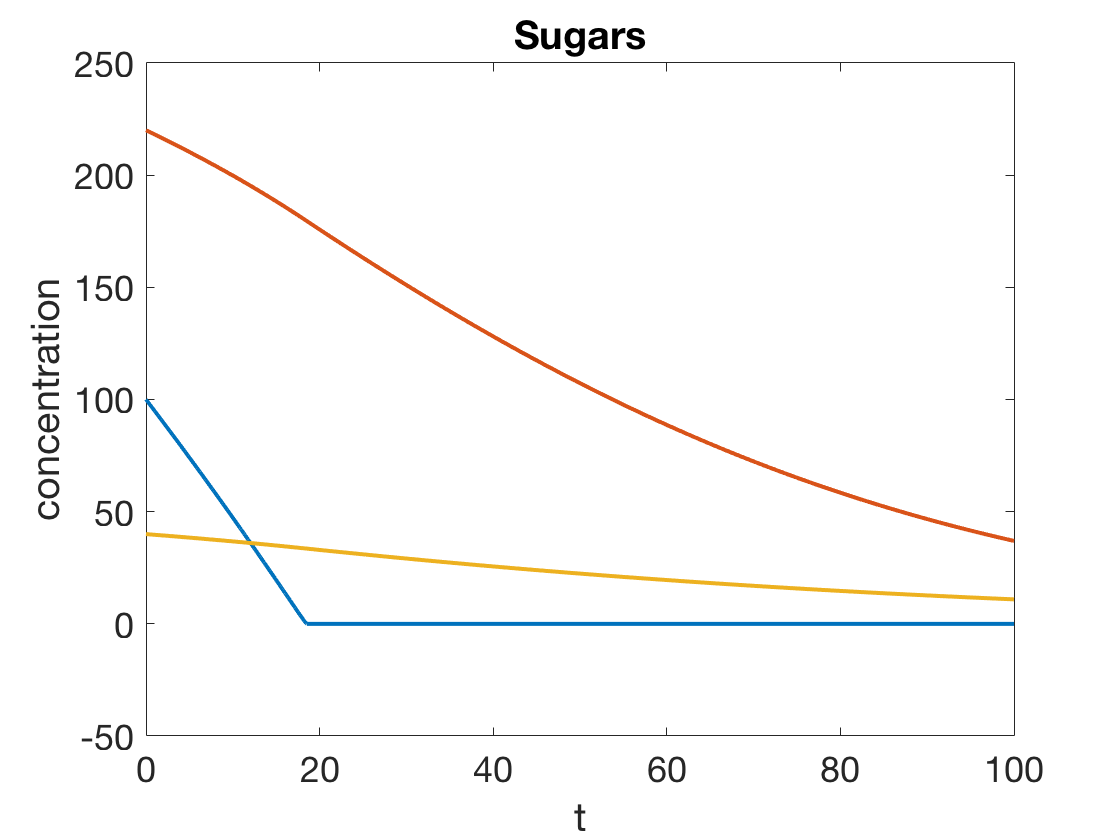

B = chebop(@beer_op,[0 100]);
B.lbc = [100; 220; 40; 180; 0 ];
[G,M,N,X,E] = B\0;
plot([G,M,N])
xlabel t, ylabel concentration
title Sugars

There is a simple conversion of $E$ to alcohol-by-volume, or ABV. 

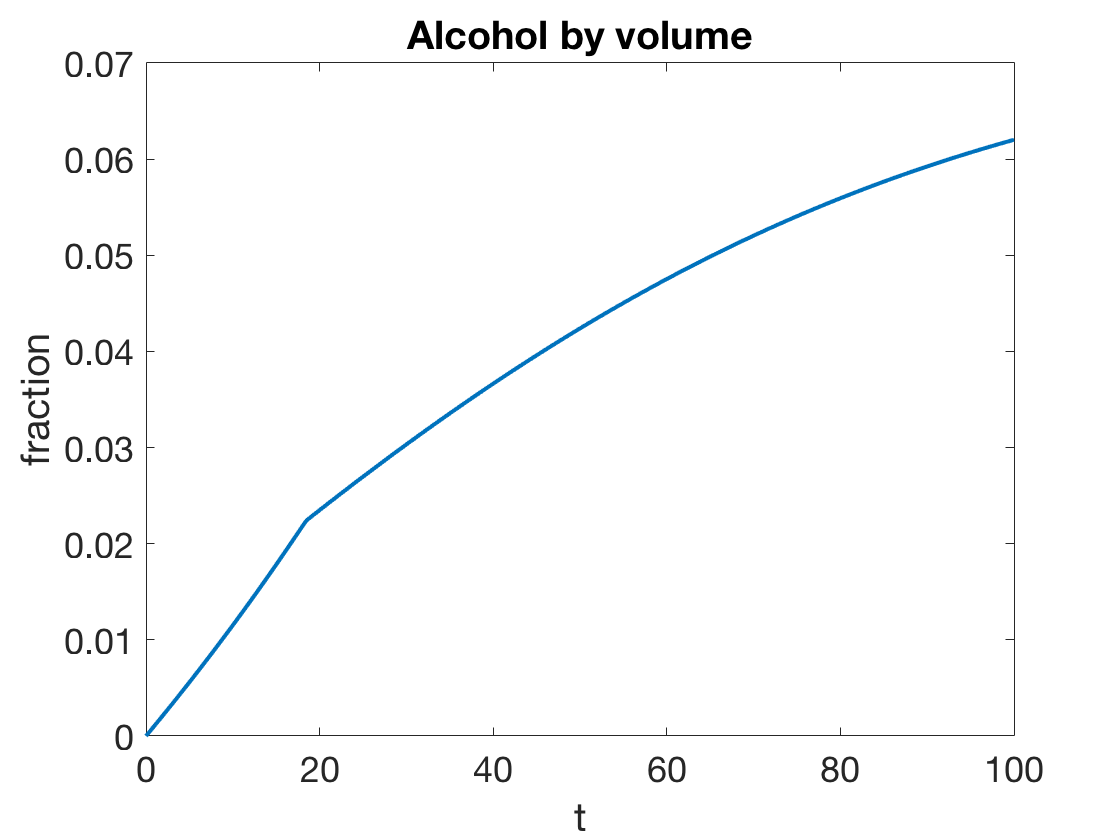

ABV = 5.837e-05*E;
plot(ABV)
xlabel t, ylabel fraction
title('Alcohol by volume')

Here we model the evolution of ABV for different initial glucose concentrations.

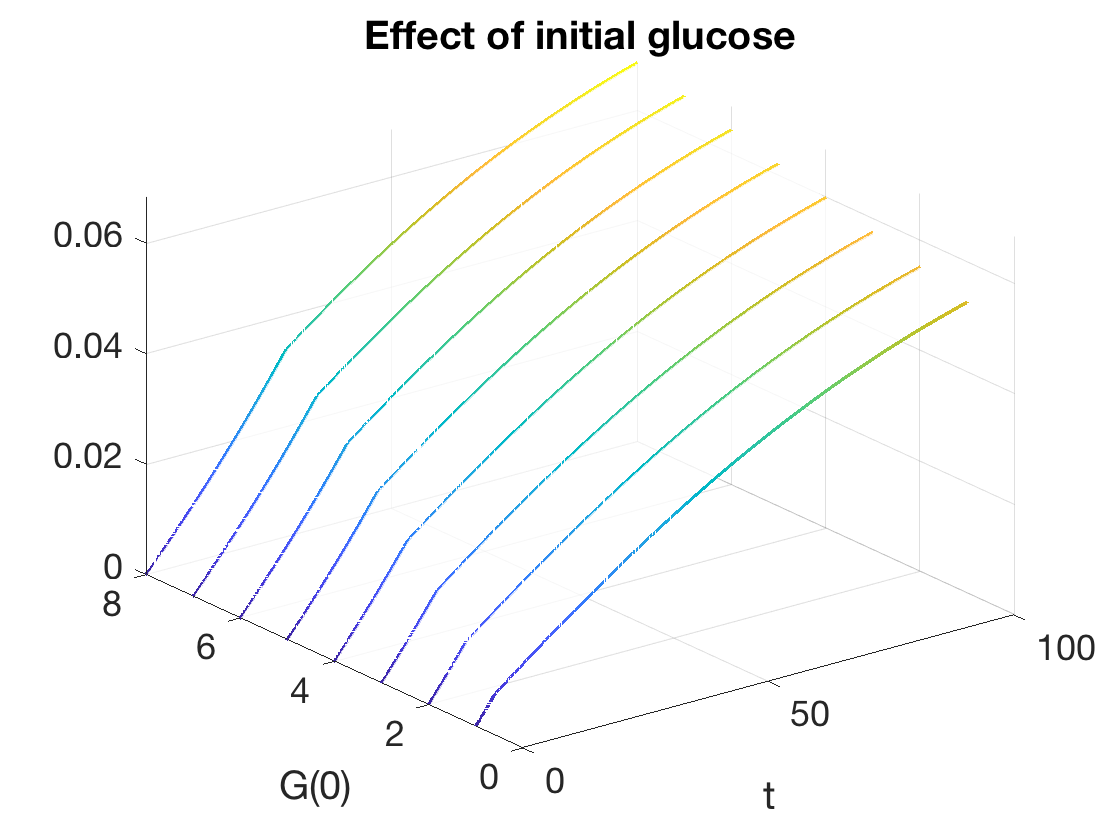

ABV = [];
for G0 = 20:20:160
    B = chebop(@beer_op,[0 100]);
    B.lbc = [G0; 220; 40; 180; 0 ];
    [G,M,N,X,E] = B\0;
    ABV = [ABV, 5.837e-05*E];
end
waterfall(ABV,'linewid',2)
xlabel t, ylabel G(0)
title('Effect of initial glucose')

Say we want to know when to stop the brewing in order to get 5% ABV. This means rootfinding on the computed solutions:

brew_times = roots(ABV-0.05)'

brew_times =    90.1969
   82.4652
   75.8805
   70.2148
   65.3034
   61.0226
   57.2772
   53.9920


The following define the ODE system. The rate constants obey Arrhenius laws. 

function [VG,VM,VN,KG,KM,KN,KiG,KiM] = arrhenius(T)
% Computes reaction parameters at the given Celsius temperature.
RT = (1.987e-3)*(T + 273.15);
VG = exp(35.77-22.6./RT);
VM = exp(16.4-11.3./RT);
VN = exp(10.59-7.16./RT);
KG = exp(-121.3+68.6./RT);
KM = exp(-19.15+14.4./RT);
KN = exp(-26.78+19.9./RT);
KiG = exp(23.33-10.2./RT);
KiM = exp(55.61-26.3./RT);
end

function u = beer_op(t,G,M,N,X,E)
[VG,VM,VN,KG,KM,KN,KiG,KiM] = arrhenius(16);
mu1 = VG*G./(KG+G);
mu2 = VM*M./(KM+M).*KiG./(KiG+G);
mu3 = VN*N./(KN+N).*KiG./(KiG+G).*KiM./(KiM+M);
u = [ 
    diff(G) - (-mu1.*X);
    diff(M) - (-mu2.*X);
    diff(N) - (-mu3.*X);
    diff(X) - (0.134*mu1+0.268*mu2+0.402*mu3).*X;
    diff(E) - (1.92*mu1+3.84*mu2+5.76*mu3).*X;
    ];
end